# BEM–PINN Framework for Solving the Laplace Equationclc

clc
clear

## Creating a 2D Grid of Points in Square shaped Domain

% Number of points along each boundary
global N_points_boundary
N_points_boundary = 20;
% Create a linearly spaced vector from 0 to 1 with N_points_boundary points
lineargrid_y = linspace(0.25, 0.75, N_points_boundary);

% shift = 0.015;
% Generate a non-uniform grid for x-axis such that points are denser near x = 0 and sparser near x = 0.5
% nonuniform_x = [linspace(0, 0.5 - shift, ((N_points_boundary-1)/2)), 0.5 ,linspace(0.5 + shift, 1, ((N_points_boundary-1)/2))];
nonuniform_x = linspace(0.25,0.75,N_points_boundary);
% Capture the middle point in the nonuniform_x vector
inner_half = nonuniform_x(ceil(N_points_boundary/2));
% Declare a global variable for half the number of points along the boundary
% global N_half_points_boundary
% Compute half the number of points along the boundary (excluding the middle point)
% N_half_points_boundary = (N_points_boundary)/2;
% Compute the grid spacing as the difference between the first two points in lineargrid
global dx
dx = diff(nonuniform_x(1:2));
% Generate a 2D grid of points using nonuniform_x for x-axis and lineargrid_y for y-axis
[X, Y] = meshgrid(nonuniform_x, lineargrid_y);
% Reshape these grid points into a single 2 x N_points_boundary^2 array where each row is a coordinate pair
XY = [X(:), Y(:)];
% Clear the X and Y variables from memory to save space
clear X Y
% Randomly shuffle the rows of XY to randomize the order of the points
XY = XY(randperm(N_points_boundary^2), :);
% Remove points from XY that are in the top right quarter, creating an L-shaped region
% XY(XY(:, 1) > 0.5, :) = [];

## Extracting Boundary and Inner Boundary Points

% Compute the boundary coordinates (BEM) using the custom function 'coordin' with specified parameters
% 'side' indicates the boundary sides
[boundaryCoords, ~, ~, side] = coordin(2*N_points_boundary, 2*N_points_boundary, [0.5; 0.5], 1, 1);

% Extract points from XY that lie on the bottom boundary (y = 0) and 
% within the left half (0 < x <= 0.5), representing the bottom boundary conditions
XY_bottom_BC = boundaryCoords(:, side ==5)';%XY(XY(:,2)==.25 & XY(:,1)<= .75 & XY(:,1)> .25, :);

% Extract points from XY that lie on the top boundary (y = 1) and 
% within the left half (x < 0.5), representing the top boundary conditions
XY_top_BC    = boundaryCoords(:, side == 7)';%XY(XY(:,2)==.75 & XY(:,1)<= .75 & XY(:,1)> .25, :);

% Extract points from XY that lie on the left boundary (x = 0) and 
% below the top boundary (y < 1), representing the left boundary conditions
XY_left_BC   = boundaryCoords(:, side == 8)';%XY(XY(:,1)==0.25 & XY(:,2)<= .75 & XY(:,2)> .25, :);

% Extract points from XY that lie on the right boundary of the top left quarter 
% (x = 0.5) and above the midpoint (y > 0.5), representing the right top boundary conditions
XY_right_BC = boundaryCoords(:, side == 6)';%XY(XY(:,1)==.75 & XY(:,2)<= .75 & XY(:,2)> .25, :);

% Extract the boundary coordinates for the right bottom side (side == 4) and transpose them
% XY_right_bottom_BC = boundaryCoords(:, side == 5)';


% Remove points from XY that are on the bottom boundary (y = 0)
XY(XY(:,2)==0.25, :) = [];

% Remove points from XY that are on the top boundary (y = 1)
XY(XY(:,2)==.75, :) = [];

% Remove points from XY that are on the left boundary (x = 0)
XY(XY(:,1)==0.25, :) = [];

% Remove points from XY that are on the right boundary at x = 0.5
XY(XY(:,1)==.75, :) = [];

% Create a column vector of zeros with length N_points_boundary-1
full_zeros = zeros(N_points_boundary, 1);

% Create a column vector of zeros with length (N_points_boundary-1)/2
half_zeros = zeros((N_points_boundary)/2, 1);

% Create a column vector of ones with length (N_points_boundary-1)/2
half_ones = ones((N_points_boundary)/2, 1);

% Create a column vector of ones with length N_points_boundary-1
full_ones = ones(N_points_boundary, 1);

% Assign the right bottom boundary coordinates to XY_BEM_BC
% XY_BEM_BC = XY_right_bottom_BC;

% Combine the boundary condition coordinates into a single array for Dirichlet boundary conditions
XY_BC_Dirichlet = [XY_bottom_BC; XY_right_BC; XY_top_BC; XY_left_BC];

% Create a corresponding array of boundary condition values for Dirichlet boundaries
U_BC_Dirichelt = [full_zeros; full_zeros; full_zeros; full_zeros];

% Assign the top boundary coordinates to XY_BC_Neumann for Neumann boundary conditions
XY_BC_Neumann = 0;

% Create a corresponding array of boundary condition values for Neumann boundaries (all ones)
dU_BC_Neumann = 0;  % 0 means X direction, 1 means Y direction: the normal direction that should have zero derivative

% Declare a global variable XY_all and combine all points (interior and boundary)
global XY_all
XY_all = [XY; XY_BC_Dirichlet];

## Visualization of Boundary and Inner Boundary Points

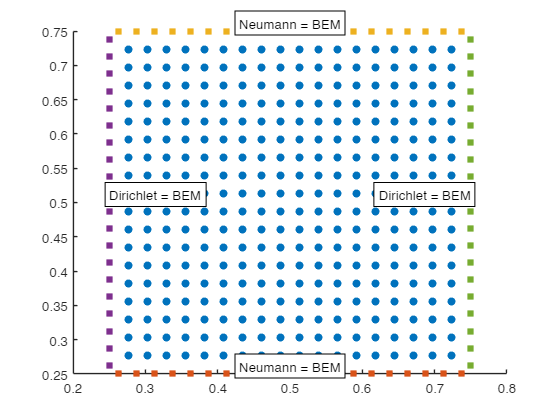


close all                % Close all open figure windows
% Closes any existing figure windows, ensuring the workspace is clear for new plots

clf                      % Clear current figure
% Clears the current figure window, removing all previous content

hold on                  % Retain current plot and add new plots to it
% Allows subsequent plots to be added to the current figure without replacing the existing plots

scatter(XY(:,1),XY(:,2), 'filled') % Scatter plot of training points
% Plots the training points using their X and Y coordinates, with filled markers

scatter(XY_bottom_BC(:,1),XY_bottom_BC(:,2), 'filled', 'square') % Scatter plot of bottom boundary points
% Plots the bottom boundary points, using filled squares as markers

scatter(XY_top_BC(:,1),XY_top_BC(:,2), 'filled', 'square')       % Scatter plot of top boundary points
% Plots the top boundary points, using filled squares as markers

scatter(XY_left_BC(:,1),XY_left_BC(:,2), 'filled', 'square')     % Scatter plot of left boundary points
% Plots the left boundary points, using filled squares as markers

scatter(XY_right_BC(:,1),XY_right_BC(:,2), 'filled', 'square')   % Scatter plot of right top boundary points
% Plots the right top boundary points, using filled squares as markers

% Adding text labels near each set of boundary points
text(mean(XY_bottom_BC(:,1)), mean(XY_bottom_BC(:,2)), 'Neumann = BEM', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', 'BackgroundColor', 'white','EdgeColor', 'black')
% Adds a text label "Dirichlet = 1" near the bottom boundary points

text(mean(XY_top_BC(:,1)), mean(XY_top_BC(:,2)), 'Neumann = BEM', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', 'BackgroundColor', 'white','EdgeColor', 'black')
% Adds a text label "Neumann = 1" near the top boundary points

text(mean(XY_left_BC(:,1)), mean(XY_left_BC(:,2)), 'Dirichlet = BEM', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', 'BackgroundColor', 'white','EdgeColor', 'black')
% Adds a text label "Dirichlet = 1" near the left boundary points

text(mean(XY_right_BC(:,1)), mean(XY_right_BC(:,2)), 'Dirichlet = BEM', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'BackgroundColor', 'white','EdgeColor', 'black')

## Converting Boundary Conditions to Deep Learning array (dlarrays)

% Applying boundary conditions to dlarrays

% Convert XY_BC_Dirichlet to dlarray with "BC" label
XY_BC_Dirichlet = dlarray(XY_BC_Dirichlet, "BC");

% Convert XY_BC_Neumann to dlarray with "BC" label
XY_BC_Neumann = dlarray(XY_BC_Neumann, "BC");

% Convert U_BC_Dirichelt to dlarray with "BC" label
U_BC_Dirichelt = dlarray(U_BC_Dirichelt, "BC");

% Convert dU_BC_Neumann to dlarray with "BC" label
dU_BC_Neumann = dlarray(dU_BC_Neumann, "BC");

% Convert XY_all to dlarray with "BC" label
XY_all = dlarray(XY_all, "BC");

% Convert XY to dlarray with "BC" label
XY = dlarray(XY, "BC");

XY_Interface1 = 0;
XY_Interface2 = 0;

XY_Interface1 = dlarray(XY_Interface1, "BC");
XY_Interface2 = dlarray(XY_Interface2, "BC");

## Define Network Parameters (Layers Architecture, Learnable Parameters such as Weights and Bias)

Define the parameters for each of the operations and include them in a structure. Use the format `parameters.operationName_ParameterName` where 

- `parameters` is the structure, 

- O`perationName` is the name of the operation (for example "fc1" (fully connected) ) 

- `ParameterName` is the name of the parameter (for example, "Weights"). 

## Convert Struct of Learnable Parameters to Vector with Names and Sizes

**Note: **Because of using `fmincon` function for solving optimization problems. parameters should be converted to a vector using the `paramsStructToVector` function.

## Define Loss and Objective Function

- **Loss Function**: Specifically refers to the function used to quantify the error between predicted and actual values in supervised learning tasks.

- **Objective Function**: This  function is  encompass the loss function and potentially other terms that reflect additional constraints or regularization.

### Anonymous function for the objective function

- The anonymous function `objFun` simplifies using `objectiveFunction` by **wrapping** it into a** single-argument function** handle.

- This is particularly useful in optimization routines where the optimizer expects the objective function to take a single input (the parameters to optimize). The other variables (`XY`, `XY_BC_Dirichlet`, etc.) are captured in the workspace at the time `objFun` is defined and are used as constants within the anonymous function.

## Trian

This section sets up an optimization using MATLAB's `fminunc` function, ensuring computational efficiency by initializing a parallel pool with all available threads. 

- It sets a maximum of 7500 function evaluations and iterations. 

- The optimization options use limited memory BFGS for Hessian approximation, a very tight optimality tolerance, and specify the objective function's gradient. Visualization is enhanced with plot functions for tracking function values and parameter histories. 

- The `UseParallel` option enables parallel computing. 

- After extracting data from `parametersV`, the `fminunc` function is called with the objective function (`objFun`) and configured options to find the optimal parameters.

**Note**: The line `'SpecifyObjectiveGradient', true, ... % Specify gradient of the objective function` tells `fminunc` to use the provided gradient of the objective function, which improves optimization efficiency and accuracy. If you set `'SpecifyObjectiveGradieabsnt'` to `false`, `fminunc` will estimate the gradient numerically rather than using the provided gradient. This can make the optimization process slower and less accurate because numerical estimation is typically less precise and more computationally intensive than using an exact gradient.

#### `fminunc` function

- It is a MATLAB function used for minimizing a scalar function of several variables without constraints. 

- This function uses gradient-based optimization techniques, such as the Quasi-Newton method with BFGS updates, to find the minimum of the objective function.

tic

minLayers = 5; %8
maxLayers = 5;
minNeurons = 45; %50
maxNeurons = 45;

% Number of random samples to test
numSamples = 1;

% Initialize variables to track the best configuration
bestLoss = inf;
bestConfig = struct();

% Arrays to store configuration details and corresponding losses
allConfigs = cell(numSamples, 1);
allLosses = zeros(numSamples, 1);

max_evals = 500; % 4000

% Weights for Dirichlet and Neumann boundary condition losses
weight_Dir_Bc = 1;
weight_Neu_Bc = 1;
weight_Dir_Bc_BEM = 1;
weight_Interface_n_Bc = 1;
weight_Interface_t_Bc = 1;


% Loop through the number of samples
for sample = 1:numSamples
    % Randomly sample the number of layers and neurons
    numLayers = randi([minLayers, maxLayers]);
    numNeurons = randi([minNeurons, maxNeurons]);

    % Initialize the parameters for the network as a structure.
    parameters = struct;

    % Initialize the parameters for the first fully connected (fc) layer.
    sz = [numNeurons 2]; % Size of the weight matrix for the first fc layer: [number of neurons, number of input channels].
    parameters.fc1_Weights = initializeHe(sz, 2, "double"); % Initialize weights using He initialization.
    parameters.fc1_Bias = initializeZeros([numNeurons 1], "double"); % Initialize biases to zeros.

    % Initialize the parameters for each of the remaining intermediate fully connected layers.
    for layerNumber = 2:numLayers-1
        name = "fc" + layerNumber; % Generate the layer name dynamically (e.g., fc2, fc3, ...).

        sz = [numNeurons numNeurons]; % Size of the weight matrix for intermediate fc layers: [number of neurons, number of neurons].
        numIn = numNeurons; % Number of input channels for the current fc layer.
        parameters.(name + "_Weights") = initializeHe(sz, numIn, "double"); % Initialize weights using He initialization.
        parameters.(name + "_Bias") = initializeZeros([numNeurons 1], "double"); % Initialize biases to zeros.
    end

    % Initialize the parameters for the final fully connected layer.
    sz = [1 numNeurons]; % Size of the weight matrix for the final fc layer: [1, number of neurons].
    numIn = numNeurons; % Number of input channels for the final fc layer.
    parameters.("fc" + numLayers + "_Weights") = initializeHe(sz, numIn, "double"); % Initialize weights using He initialization.
    parameters.("fc" + numLayers + "_Bias") = initializeZeros([1 1], "double"); % Initialize biases to zeros.

    % Convert parameters struct to vector format
    global parameterNames parameterSizes
    [parametersV, parameterNames, parameterSizes] = parameterStructToVector(parameters);

    % Define an anonymous function for the objective function
    objFun = @(parameters) objectiveFunction(...
        parameters, ...                          % Input: parameters vector or structure
        XY, ...                                  % Input: XY data
        XY_BC_Dirichlet, ...                     % Input: XY_BC_Dirichlet data
        XY_BC_Neumann, ...                       % Input: XY_BC_Neumann data
        XY_Interface1,... 
        XY_Interface2,...
        U_BC_Dirichelt, ...                      % Input: U_BC_Dirichelt data
        dU_BC_Neumann, ...                       % Input: dU_BC_Neumann data
        parameterNames, ...                      % Input: parameterNames (assumed to be part of the objective function)
        parameterSizes,...
        weight_Dir_Bc,...
        weight_Neu_Bc,...
        weight_Dir_Bc_BEM, ...
        weight_Interface_n_Bc, ...
        weight_Interface_t_Bc);                         % Input: parameterSizes (assumed to be part of the objective function)

    % Set up initial parameters for optimization using fminunc
    if (isempty(gcp('nocreate')))
        parpool('Threads') % Create parallel pool using all available threads
    end

    % "fminunc", ...
    % dfp    

    options = optimoptions('fminunc','HessianApproximation', "lbfgs", ... % Approximate Hessian using limited memory BFGS
        'MaxIterations', max_evals, ...      % Maximum number of iterations
        'MaxFunctionEvaluations', max_evals, ...  % Maximum number of function evaluations
        'OptimalityTolerance', 0, ...  % Optimality tolerance
        'StepTolerance', 0,...
        'SpecifyObjectiveGradient', true,...
        'UseParallel', true);%, ... % Specify gradient of the objective function
        % 'PlotFcn', { ...                      % Plot functions for visualization
        %     "optimplotfval", ...              % Plot function values
        %     @(x, optimValues, state) plotU2(x, optimValues, state, XY_all, parameterNames, parameterSizes), ... % Custom plot function
        %     @plotHistory_f, ...               % Plot history of objective function values
        %     @plotHistory_u, ...               % Plot history of parameter updates
        %     @plotHistory_du, ...              % Plot history of gradient updates
        %     @plotHistory_Energy ...           % Plot history of energy
        % }, ...
        % 'UseParallel', true);                 % Use parallel computing if available

    global history iter;

    history.loss = zeros(1, max_evals);     % Loss function values
    history.loss_f = zeros(1, max_evals);     % Loss function values
    history.loss_u = zeros(1, max_evals);     % Loss for u variables
    history.loss_du = zeros(1, max_evals);    % Loss for du variables
    history.loss_bem = zeros(1, max_evals);    % Loss for du variables
    % history.loss_energy = zeros(1, max_evals);% Energy loss values
    % history.loss_normal_interface = zeros(1, max_evals);% Energy loss values
    % history.loss_tangential_interface = zeros(1, max_evals);% Energy loss values    

    iter = 0;  % Iteration count

    parametersV = extractdata(parametersV);

    % Perform optimization using fminunc with specified objective function and options
    [parametersV, fval, exitflag, output] = fminunc(objFun, parametersV, options);

    % Store the current configuration and its loss
    allConfigs{sample} = struct('numLayers', numLayers, 'numNeurons', numNeurons, 'loss', fval);
    allLosses(sample) = fval;

    % Check if the current configuration is the best so far
    if fval < inf
        bestLoss = fval;
        bestConfig.numLayers = numLayers;
        bestConfig.numNeurons = numNeurons;
        bestConfig.parametersV = parametersV;
        bestConfig.parameterNames = parameterNames;
        bestConfig.parameterSizes = parameterSizes;
    end
end


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


toc

Elapsed time is 1.775229 seconds.



% Plot the loss for each configuration
% figure;
% bar(allLosses);
% title('Loss for Different Configurations');
% xlabel('Configuration Number');
% ylabel('Loss');
% xticks(1:numSamples);
% xticklabels(cellfun(@(c) sprintf('L%d-N%d', c.numLayers, c.numNeurons), allConfigs, 'UniformOutput', false));
% xtickangle(45);
% grid on;

% Display the best configuration and its loss
disp("Best Configuration:");

Best Configuration:


disp("Number of Layers: " + bestConfig.numLayers);

Number of Layers: 5


disp("Number of Neurons: " + bestConfig.numNeurons);

Number of Neurons: 45


disp("Loss: " + bestLoss);

Loss: 0.10782



% Use the best configuration for further evaluation or deployment
parametersV = bestConfig.parametersV;
parameterNames = bestConfig.parameterNames;
parameterSizes = bestConfig.parameterSizes;

## Evaluate Model Accuracy

This segment first assigns `XY_all` to `XY_test`, using the full dataset as the test set. It then evaluates the model with the current parameters on this test set, storing the result in `U`. Finally, the code computes the total gradient of the objective function with respect to the parameters using `dlfeval` and the `gradient_calc_sum` function, storing the computed gradients in `du_tot`. This process is essential for optimizing the model parameters by providing the necessary gradient information to guide the optimization algorithm.

% For prediction, convert the vector of parameters to a structure using the parameterVectorToStruct function (attached to this example as a supporting file).
parameters = parameterVectorToStruct(parametersV,parameterNames,parameterSizes);
% Use the full dataset as the test set
XY_test = XY_all;  
% Evaluate the model with the current parameters on the test set
U = model(parameters, XY_test);  
% Compute the total gradient of the objective function with respect to the parameters
du_tot = dlfeval(@gradient_calc_sum, parameters, XY_test);
% Function to Calculate the Gradient of the Sum of the Model Output with Respect to X
function dU = gradient_calc_sum(parameters, X)
    % Calculate the gradient of the sum of the model output with respect to X
    dU = dlgradient(sum(model(parameters, X), "all"), X);
end

X_test = extractdata(XY_test(1,:));
Y_test = extractdata(XY_test(2,:));
U_predicted = extractdata(U(1,:));
dUx_predicted = -extractdata(du_tot(1,:));
dUy_predicted = -extractdata(du_tot(2,:));
% Assuming x_test, y_test, and u_predict are already defined in your workspace

save('data.mat','X_test', 'Y_test', 'U_predicted', 'dUx_predicted', 'dUy_predicted');

## BEM solver for the full domain

% contourf(Xq, Yq, dUxq, 200, 'LineColor', 'none');
load('data.mat', 'X_test', 'Y_test', 'U_predicted', 'dUx_predicted', 'dUy_predicted');

[x0, y0, valore] =...
    bemforpinn_fun_full((1./20).*dUx_predicted(X_test==.75 & Y_test>=.25 & Y_test<=.75),...
    (1/20).*dUx_predicted(X_test==.25 & Y_test>=.25 & Y_test<=.75),...
    U_predicted(X_test<=.75 & X_test>=.25 & Y_test==.25), ...
    U_predicted(X_test<=.75 & X_test>=.25 & Y_test==.75),2*N_points_boundary);
save('data_bem.mat','x0', 'y0', 'valore');

## **Visualization of Scalar Potential**

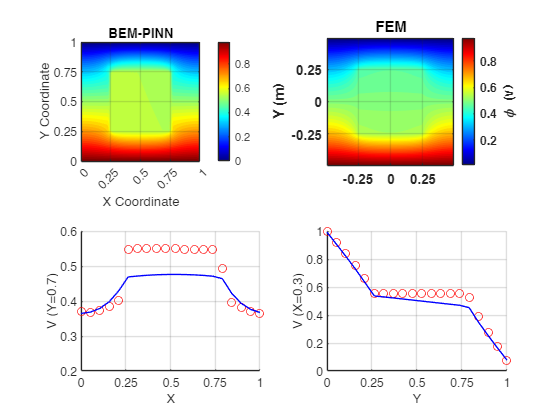

subplot(2, 2, 1);

load('data_bem.mat','x0', 'y0', 'valore');
load('data.mat', 'X_test', 'Y_test', 'U_predicted', 'dUx_predicted', 'dUy_predicted');

% Convert grids to vectors
% x0(:,1)=[];
% y0(:,1)=[];
% valore(:,1)=[];

x_vector = x0(:);
y_vector = y0(:);
u_vector = valore(:);
nan_ind = isnan(u_vector);
u_vector(nan_ind) = [];
x_vector(nan_ind) = [];
y_vector(nan_ind) = [];

% Combine x and y coordinates
x_total = [x_vector', X_test];
y_total = [y_vector', Y_test];

% Combine U values
U_total = [u_vector', U_predicted];

% Define the grid range and resolution
x_min = min(x_total);
x_max = max(x_total);
y_min = min(y_total);
y_max = max(y_total);

grid_resolution = 100; % You can adjust this value

% Create grid vectors
x_grid = linspace(x_min, x_max, grid_resolution);
y_grid = linspace(y_min, y_max, grid_resolution);

% Create a meshgrid
[X_grid, Y_grid] = meshgrid(x_grid, y_grid);

% Interpolate the U_total values onto the grid
U_grid = griddata(x_total, y_total, U_total, X_grid, Y_grid, 'natural');
% Plot the contour

contourf(X_grid, Y_grid, U_grid, 50, 'LineColor', 'none');
colorbar;
title('Contour Plot of Combined Data');
xlabel('X Coordinate');
ylabel('Y Coordinate');
% clim([0 1]);
colormap jet;
title('BEM-PINN');
xlabel('X Coordinate');
ylabel('Y Coordinate');
% clim([0 1]);
colormap jet;
axis equal;
ax = gca;
ax.XTick = 0:0.25:1;
ax.YTick = 0:0.25:1;
grid on

% % Load data from the text file
data = load('Cavity_1_20.txt');

% Separate each column into different matrices
x_fem = data(:, 1);  % First column
y_fem = data(:, 2);  % Second column
v_fem = data(:, 3);  % Third column

x_unique = unique(x_fem);
y_unique = unique(y_fem);

[X, Y] = meshgrid(x_unique, y_unique);

% Reshape z values to match the grid
Z = reshape(v_fem, length(y_unique), length(x_unique));

subplot(2, 2, 2);

% Plot the contour
contourf(Y, X, Z/10, 50, 'LineColor', 'none');
axis equal;
colorbar;  % Optional: add a color bar to show the scale
colorbar;
ylabel('Y (m)');
% xlim([0 1]);
% ylim([0 1]);
% clim([0 10]);
colormap jet;
cb = colorbar;
ylabel(cb, '\phi (v)', 'FontSize', 10, 'FontWeight', 'bold');
set(gca, 'FontSize', 10, 'FontWeight', 'bold');
title('FEM')
grid on;
% text(0.16, 0.63, '\epsilon_r = 1', 'FontSize', 15, 'Color', 'k');
% text(0.65, 0.25, '\epsilon_r = 20', 'FontSize', 15, 'Color', 'k');
set(gcf, 'Color', 'w');
yticks([0 .25 .5 .75 1]);  % Tick positions for the y-axis
axis equal;

grid on;
% text(0.16, 0.5, 'PINN', 'FontSize', 12, 'Color', 'b');
% text(0.65, 0.25, 'BEM', 'FontSize', 12, 'Color', 'b');
ax = gca;
ax.XTick = -.5:0.25:.5;
ax.YTick = -.5:0.25:.5;
hold off

% Subplot 2x2, position 3
subplot(2, 2, 3);
hold on
plot(linspace(0, 1, 20),U_grid(70,1:5:end),'ro')
plot(linspace(0, 1, 20),Z(1:5:end,70)/10,'b')
ylim([0.2,0.6])
xlim([0, 1])
% title('Plot 3: U\_grid vs Z/10')  % Adding title
xlabel('X')            % X-axis label
ylabel('V (Y=0.7)')            % Y-axis label
grid on                           % Enabling grid
ax = gca;
ax.XTick = 0:0.25:1;

hold off

% Subplot 2x2, position 4
subplot(2, 2, 4);
hold on
plot(linspace(0, 1, 20),U_grid(1:5:end,30),'ro')
plot(linspace(0, 1, 20),Z(30,1:5:end)/10,'b')
ylim([0,1])
xlim([0, 1])
% title('Plot 4: U\_grid vs Z/10')  % Adding title
xlabel('Y')            % X-axis label
ylabel('V (X=0.3)')            % Y-axis label
grid on                           % Enabling grid
ax = gca;
ax.XTick = 0:0.25:1;

hold off

% Save the structure to a .mat file
save('history_BEMPINN.mat', 'history');
% parameters = model.Layers; % Extract all layers including their parameters
% save('modelParameters.mat', 'parameters');